# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

clearvars; clc;
patients = find_patients('eeg');
patient = patients{1};

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ah7


info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

% Weights for channels and frequencies.
features_weight = load('features_filter.mat').features_filter';

## load EEG for offline data - compute Laplacian referencing and PSD

PSD_data = {};
for f = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


[offline.PSD, offline.EVENT, offline.run_k] = concatenatePSD(PSD_data);

## common data

here we suppose the frequecies of the PSD don't change between the files

info.frequencies = PSD_data{1}.frequencies;

## load EEG for online data - compute Laplacian referencing and PSD

PSD_data = {};
for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


[online.PSD, online.EVENT, online.run_k] = concatenatePSD(PSD_data);

## label data

[offline.cue_k, offline.trial_k] = label_data(offline.EVENT, length(offline.PSD));
[online.cue_k, online.trial_k] = label_data(online.EVENT, length(online.PSD));

## log and sub-frequences extraction

offline.PSD = extract_frequencies(offline.PSD, info.frequencies, info.selected_frequencies);
offline.PSD = log(offline.PSD); 

% only at last update the frequences
[online.PSD, info.frequencies] = extract_frequencies(online.PSD, info.frequencies, info.selected_frequencies);
online.PSD = log(online.PSD); 

## convert PSD into dataset for the classifiers

classes = [info.cue_BF, info.cue_BH];
[selected_features , fisher_score_run] = psd2features(offline.PSD, offline.run_k, offline.cue_k, classes, info.num_features, features_weight);
offline.dataset = extract_features(offline.PSD, selected_features);
% 
% online.features = extractFeatures(online.PSD, selected_freq_chan_index);
%%%% to be equal to the prof
selected_features={[10 9],[11 9],[5 8]};
offline.dataset = extract_features(offline.PSD, selected_features);
online.dataset = extract_features(online.PSD, selected_features);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run,3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* features_weight;

## generate map of selected features

features_matrix = feature_map(selected_features,size(mean_fisher_score));

## Visualization Fisher score

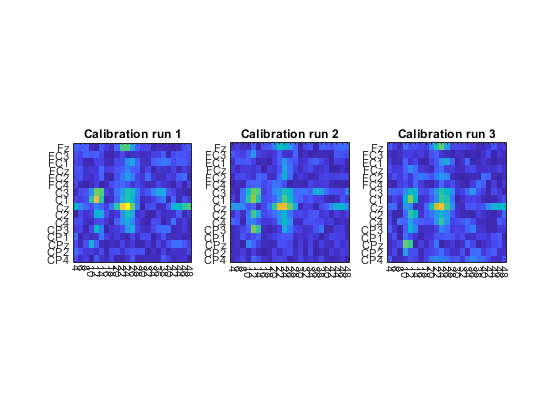

plot_fisher_score(info, info.frequencies, fisher_score_run);

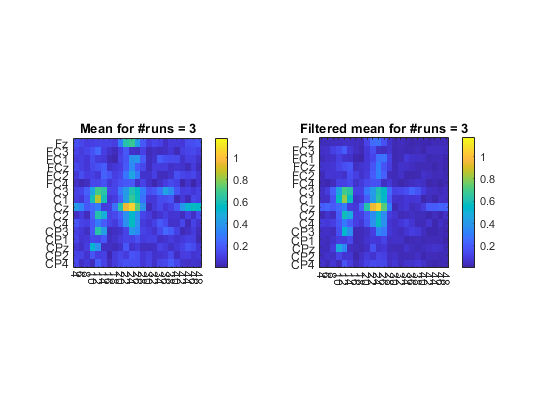

plot_average_fisher(info, info.frequencies, fisher_score_run, features_weight);

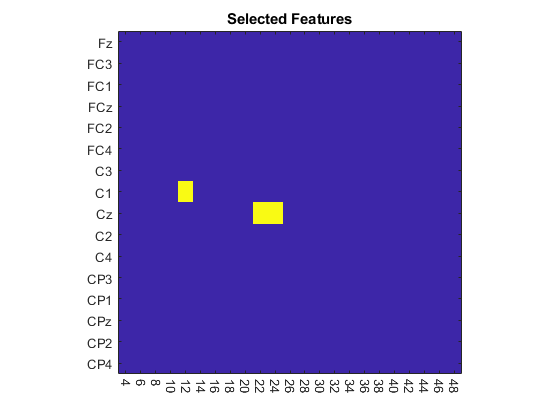

plot_selected_features(info, info.frequencies, fisher_score_run, selected_features);

## extract training set

bh_index = (offline.cue_k== info.cue_BH);
bf_index = (offline.cue_k== info.cue_BF);

train_set.data = offline.dataset(bh_index | bf_index, :);
train_set.true_labels = offline.cue_k(bh_index | bf_index);

## train classifier

%model = train_binary_model(train_set, label_train);
model = fitcdiscr(train_set.data, train_set.true_labels, "DiscrimType", "quadratic");

## train set results

predicted_labels = predict(model, train_set.data);
[accuracy, accuracy_per_class] = evaluate_classifier(train_set.true_labels, predicted_labels, classes)

accuracy = 81.8371

accuracy_per_class =    75.9367   87.7358


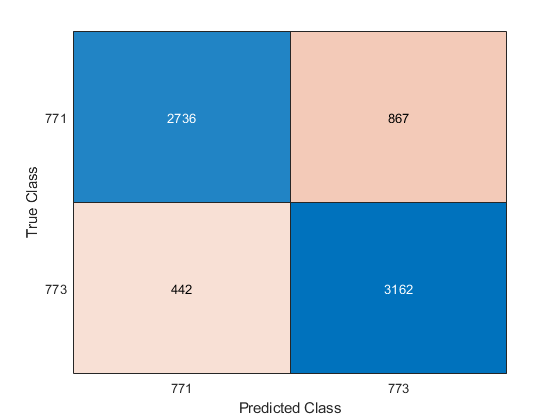

figure;
confusionchart(train_set.true_labels, predicted_labels);

## extract test set

bh_index = (online.cue_k== info.cue_BH);
bf_index = (online.cue_k== info.cue_BF);

test_set.data = online.dataset(bh_index | bf_index, :);
test_set.true_labels = online.cue_k(bh_index | bf_index);

## test the model on online data

predicted_labels = predict(model, test_set.data);
[accuracy, accuracy_per_class] = evaluate_classifier(test_set.true_labels, predicted_labels, classes)

accuracy = 73.4216

accuracy_per_class =    74.8002   72.5689


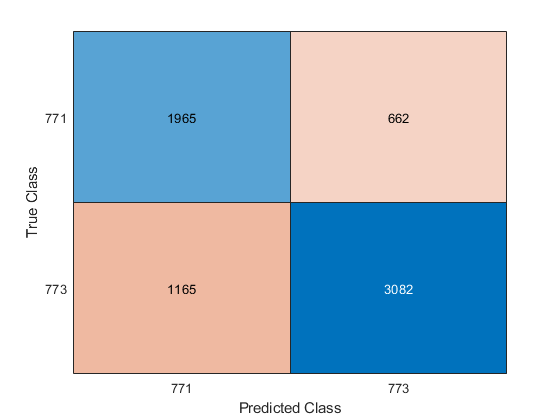

confusionchart(test_set.true_labels, predicted_labels);

# Evidence Accumulation

classify and accumulate evidence over the feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

## data

% online data
accumulation_data = online.dataset;
%predict on data
[~,post_probabilities] = predict(model, accumulation_data);

num_samples = length(accumulation_data);
num_classes = length(classes);
% reset accumulation to the base probability of this class = 1/num_classes
reset_accumulation = 1./num_classes;
% vector of start of feedback for each trial
feedback_starts = online.EVENT.POS(online.EVENT.TYP==info.feedback_code);

## Exponential smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
%alpha_ex = 0.9; 
alpha_ex = 0.97; 
% compute accumulator
accumulator_ex = exponential_smoothing(post_probabilities, num_classes, feedback_starts, alpha_ex);

## Dynamic smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_dyn = 0.5;
beta = 0.11;
conservative_amp = 0.1;
w = 0.3;
free_force_function = @(x) f_free(x,conservative_amp,w);
bmi_force_function = @(x) f_bmi_sin(x);

% compute accumulator
accumulator_dyn = dynamic_smoothing(post_probabilities, num_classes, feedback_starts, alpha_dyn, beta, free_force_function, bmi_force_function);

## moving average

alpha_mov = 0.4;
% compute accumulator
accumulator_mov = mov_avg_smoothing(post_probabilities, num_classes, feedback_starts, alpha_mov);

# EVIDENCE ACCUMULATION PERFORMANCE

## data


% index for the feedback part of the data used in accumulation
feedback_index = labels_for_event(online.EVENT, info.feedback_code, length(online.PSD));
% vector of true class for the trial
true_class = online.EVENT.TYP(online.EVENT.TYP==info.cue_BF | online.EVENT.TYP==info.cue_BH | online.EVENT.TYP==info.cue_rest);

up_threshold_ex = 0.7;
down_threshold_ex = 0.3;
up_threshold_dyn = 0.77;
down_threshold_dyn = 0.3;
up_threshold_mov = 0.7;
down_threshold_mov = 0.3;

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(up_threshold_ex, down_threshold_ex, true_class, accumulator_ex, feedback_index, online.trial_k)

perf_active_ex = 83.7500

perf_resting_ex = 17.5000

perf_active_rej_ex = 85.8974

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(up_threshold_dyn, down_threshold_dyn, true_class, accumulator_dyn, feedback_index, online.trial_k)

perf_active_dyn = 76.2500

perf_resting_dyn = 2.5000

perf_active_rej_dyn = 77.2152

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(up_threshold_mov, down_threshold_mov, true_class, accumulator_mov, feedback_index, online.trial_k)

perf_active_mov = 67.5000

perf_resting_mov = 2.5000

perf_active_rej_mov = 67.5000

function fig = plot_fisher_score(info, psd_frequencies, fisher_score)

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
handles = nan(runs, 1);
fig = figure;

for r = 1:runs
    subplot(1, runs, r);
    imagesc(fisher_score(:, :, r)');
    axis square;
    set(gca, 'XTick', 1:freq);
    set(gca, 'XTickLabel', psd_frequencies);
    set(gca, 'YTick', 1:chan);
    set(gca, 'YTickLabel', info.channel_labels);
    xtickangle(-90);
    title(['Calibration run ' num2str(r)]);
    caxis([m, M]);
    handles(r) = gca;
end

end

function fig = plot_average_fisher(info, psd_frequencies, fisher_score, feature_weights)

mean_fisher = mean(fisher_score, 3);
filt_fisher = mean_fisher .* feature_weights;

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

subplot(1,2,1);
imagesc(mean_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Mean for #runs = ' num2str(runs)]);

subplot(1,2,2);
imagesc(filt_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Filtered mean for #runs = ' num2str(runs)]);

end

function fig = plot_selected_features(info, psd_frequencies, fisher_score, selected_features)

features_mask = zeros(size(fisher_score(:,:,1)));

for k = 1 : length(selected_features)
    feature_index = selected_features{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
title('Selected Features');

end